# 小さなWebでのページランク算出のサンプル

clear;clc;close all;

リンクデータを読み込む

tbl=readtable('../data/smallWebExample.xlsx');
G=digraph(tbl.From, tbl.To)

G =   digraph のプロパティ:

    Edges: [20×1 table]
    Nodes: [10×1 table]


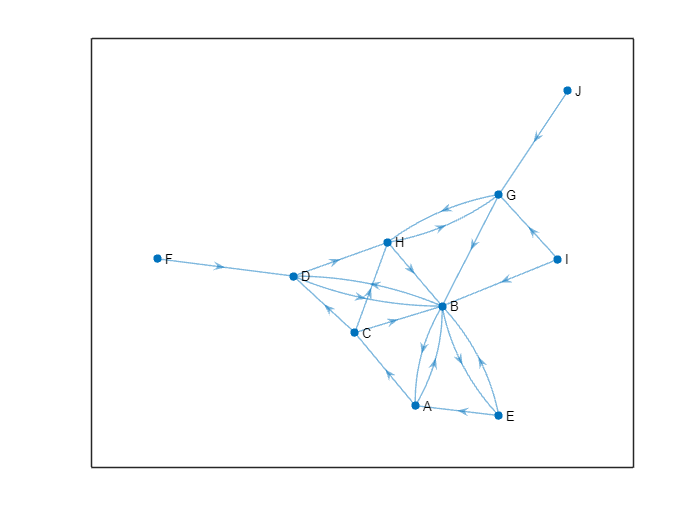

plot(G);
exportgraphics(gcf,'fig_pageRankSample.pdf')

グラフから隣接行列を求める機能を使う．行と列に注意する．

V=G.adjacency';V=full(V);
S=V./sum(V);S(isnan(S))=0;
S=S

S =          0    0.3333         0         0    0.5000         0         0         0         0         0
    0.5000         0    0.3333    0.5000    0.5000    0.5000         0    0.5000    0.5000         0
    0.5000         0         0         0         0         0         0         0         0         0
         0    0.3333    0.3333         0         0         0    1.0000         0         0         0
         0    0.3333         0         0         0         0         0         0         0         0
         0         0    0.3333    0.5000         0         0         0    0.5000         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.5000         0         0    0.5000    1.0000
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0       

b=0.85;
r=ones(size(S,1),1)/size(S,1);
for k=1:20
    r=b*S*r+(1-b)/size(S,1);
    r=r/sum(r);
end
r=inv(eye(size(S))-b*S)*(1-b)*ones(size(S,1),1)/size(S,1);

定義を実装したpagerank

r=r/sum(r)

r =     0.1394
    0.2924
    0.0743
    0.1317
    0.0979
    0.1300
    0.0150
    0.0894
    0.0150
    0.0150


MATLABで用意されている関数で算出したpagerank

centrality(G,"pagerank",'FollowProbability',b);
ans/sum(ans)

ans =     0.1394
    0.2924
    0.0743
    0.1316
    0.0979
    0.1300
    0.0150
    0.0893
    0.0150
    0.0150


G.Nodes.PageRank = r;
G.Nodes.InDegree = indegree(G);
G.Nodes.OutDegree = outdegree(G);

PageRank:ページランク

InDegree:リンクが入ってくる個数

OurDegree:リンクが出ていく個数

G.Nodes

ans = 10×4 table
    Name     PageRank    InDegree    OutDegree
    _____    ________    ________    _________

    {'A'}     0.13945       2            2    
    {'B'}     0.29244       7            3    
    {'C'}    0.074265       1            3    
    {'D'}     0.13165       3            2    
    {'E'}    0.097858       1            2    
    {'H'}     0.12997       3            2    
    {'F'}       0.015       0            1    
    {'G'}    0.089363       3            2    
    {'I'}       0.015       0            2    
    {'J'}       0.015       0            1    


sortrows(ans,"InDegree","descend")

ans = 10×4 table
    Name     PageRank    InDegree    OutDegree
    _____    ________    ________    _________

    {'B'}     0.29244       7            3    
    {'D'}     0.13165       3            2    
    {'H'}     0.12997       3            2    
    {'G'}    0.089363       3            2    
    {'A'}     0.13945       2            2    
    {'C'}    0.074265       1            3    
    {'E'}    0.097858       1            2    
    {'F'}       0.015       0            1    
    {'I'}       0.015       0            2    
    {'J'}       0.015       0            1    


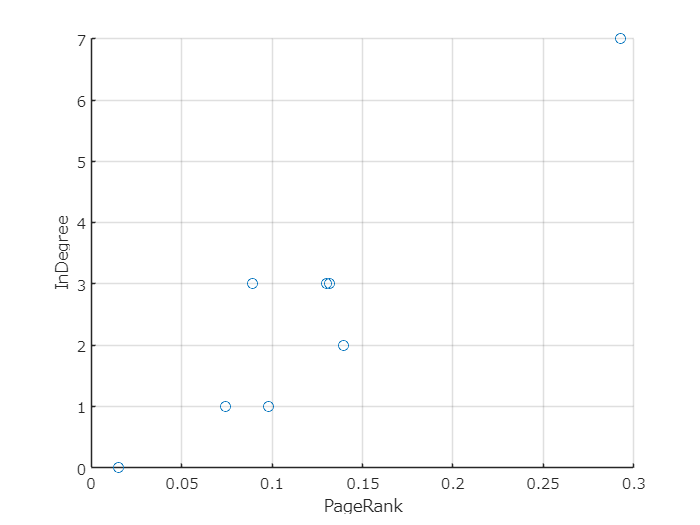

figure;
scatter(G.Nodes.PageRank, G.Nodes.InDegree);
set(gca,'fontname','メイリオ');grid on;
xlabel('PageRank');ylabel("InDegree");